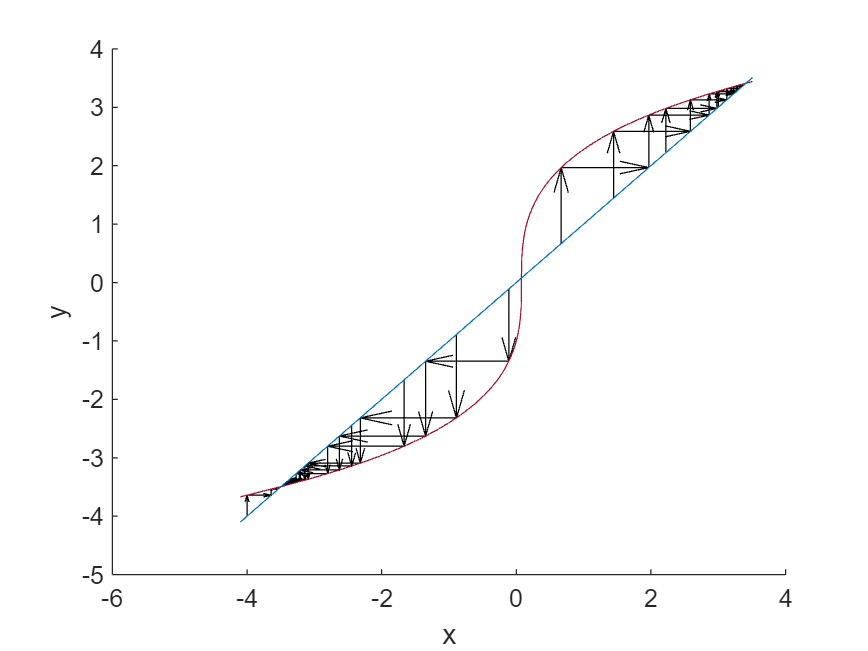

clear
f1 = @(x)(nthroot(12*x+sin(x)-1,3)); % iteration founction, remember to add '.'
x = linspace(-4,3,10); % initial values
t = 100;% iteration times, where t starts from 0
graphAnalysis(f1,x,t)

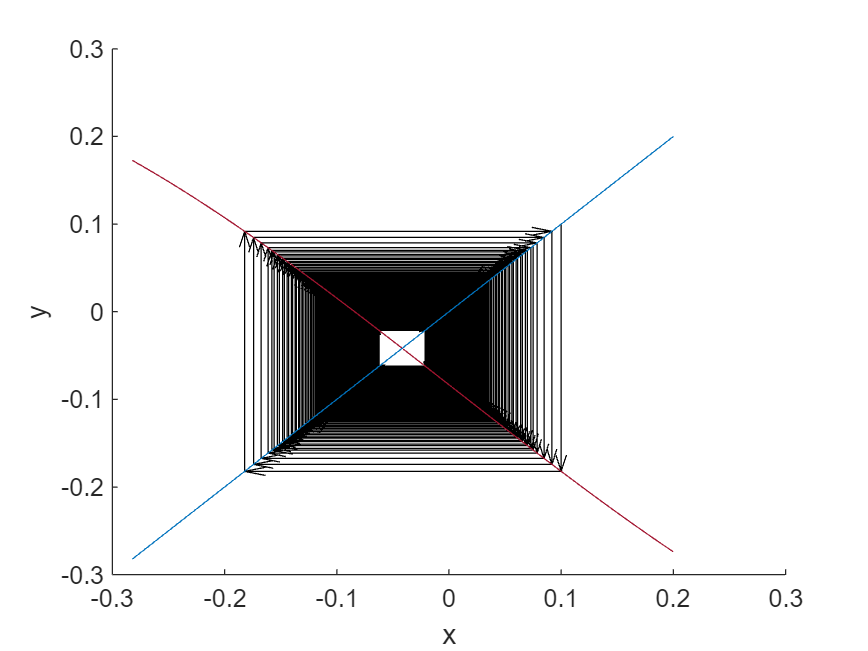

f2 = @(x)((x.^3-sin(x)-1/12)); % iteration founction, remember to add '.'
x = linspace(0,0.1,5); % initial values
t = 100;% iteration times, where t starts from 0
graphAnalysis(f2,x,t)

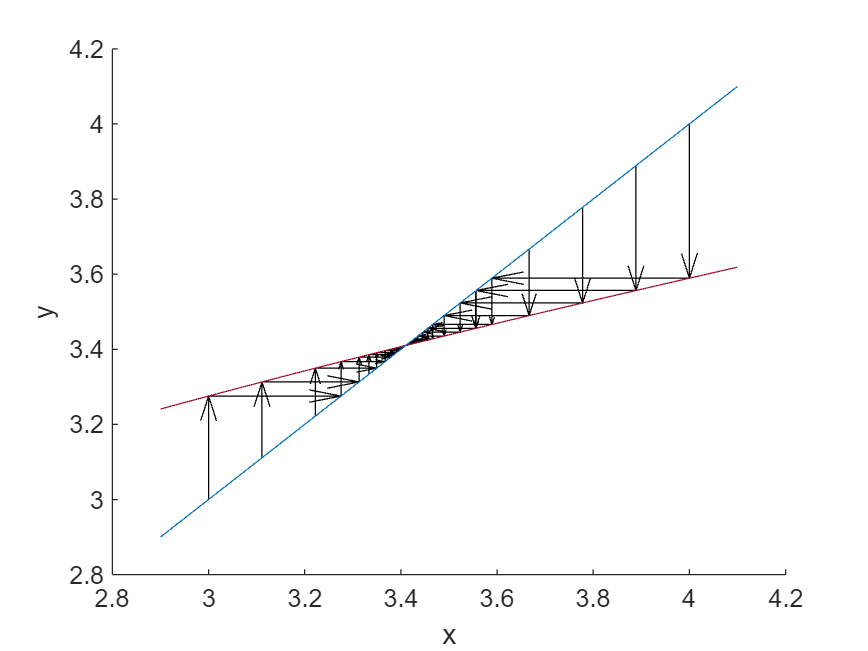

f3 = @(x)(nthroot(12*x+sin(x)-1,3)); % iteration founction, remember to add '.'
x = linspace(3,4,10); % initial values
t = 100;% iteration times, where t starts from 0
graphAnalysis(f3,x,t)

A = eye(20)*2 + ones(20,20) - triu(ones(20,20),3) - triu(ones(20,20),3)';
y = rand(20,1)*2-1

y =    0.993700429149897
   0.107083146991065
   0.030916909680652
  -0.338635868019466
  -0.139996403213207
  -0.016387492792511
  -0.857925832174095
   0.775478431065432
  -0.870732817898263
  -0.127630088537103


b = A*y;
t = 100;

For Jacobi's iteration:

x = rand(20,1)*2-1;
Dinv = eye(20)/3;
LU = A - eye(20)*3

LU =      0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

err = zeros(t,1);
for k = 1:t
    x = Dinv*(b-LU*x);
    err(k) = norm(y-x);
end
eig(Dinv*LU)

ans =   -0.726115830293049
  -0.723208231621337
  -0.655443495765127
  -0.647181152207062
  -0.540253949283409
  -0.534584004493780
  -0.403201724322253
  -0.383731181114612
  -0.269239944070692
  -0.202703740554692


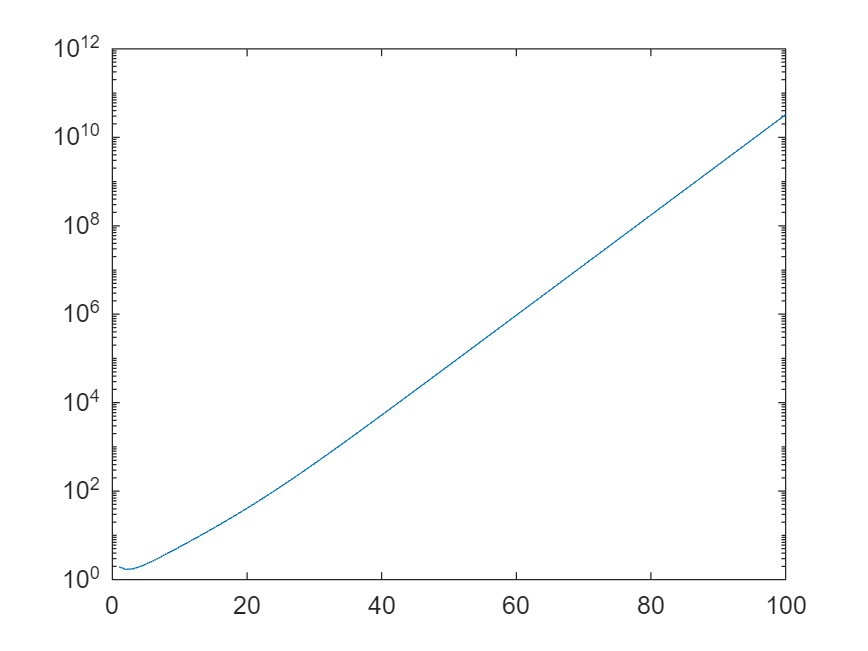

clf
semilogy(err)

For Gaussian Method:

x = rand(20,1)*2-1

x =    0.338085180163111
   0.000422648562205
  -0.564012402499693
   0.143231450808178
  -0.755621698153160
   0.342332465977306
   0.199171096245628
  -0.888047685224419
  -0.887313962913286
  -0.694998725995059


err = zeros(t,1);
U = triu(A,1);
L = A-U;
for k = 1:100
    x = L\(b-U*x);
    err(k) = norm(y-x);
end
norm(y-x)

ans =      5.721327364981972e-16


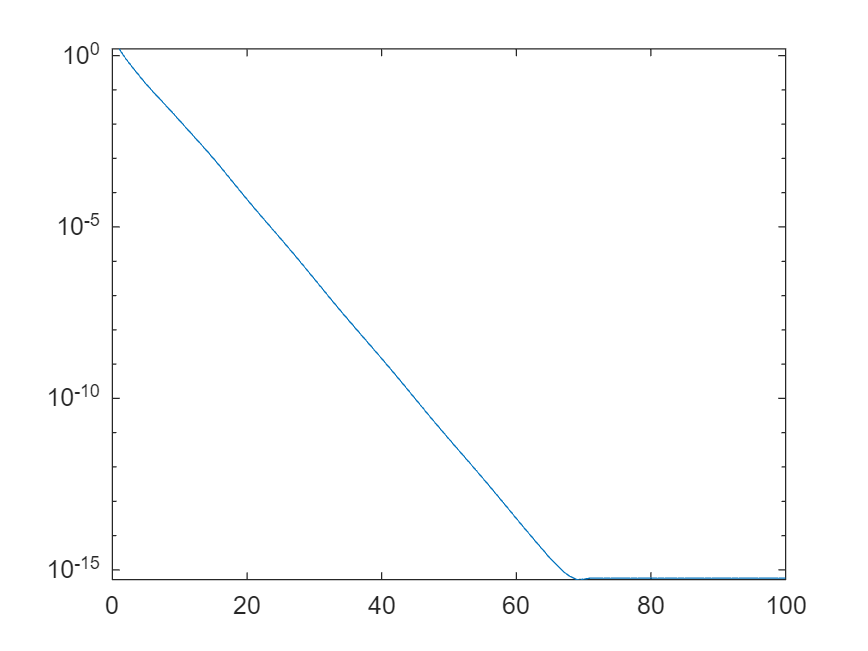

clf
semilogy(err)

abs(eig(L\U))

ans =                    0
   0.585803816007615
   0.585803816007615
   0.497608406583727
   0.497608406583727
   0.378270957628480
   0.378270957628480
   0.255792796096772
   0.255792796096772
   0.149613529066138


Method I:

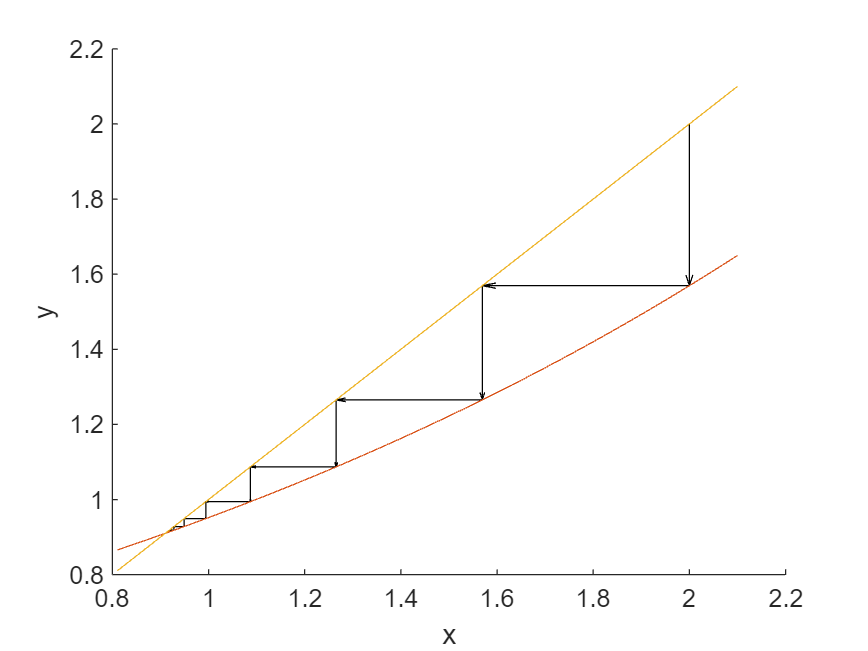

f = @(x)(sqrt(exp(x)/3)); % iteration founction, remember to add '.'
x = 2; % initial values
t = 10;% iteration times, where t starts from 0
graphAnalysis(f,x,t)

Method II:

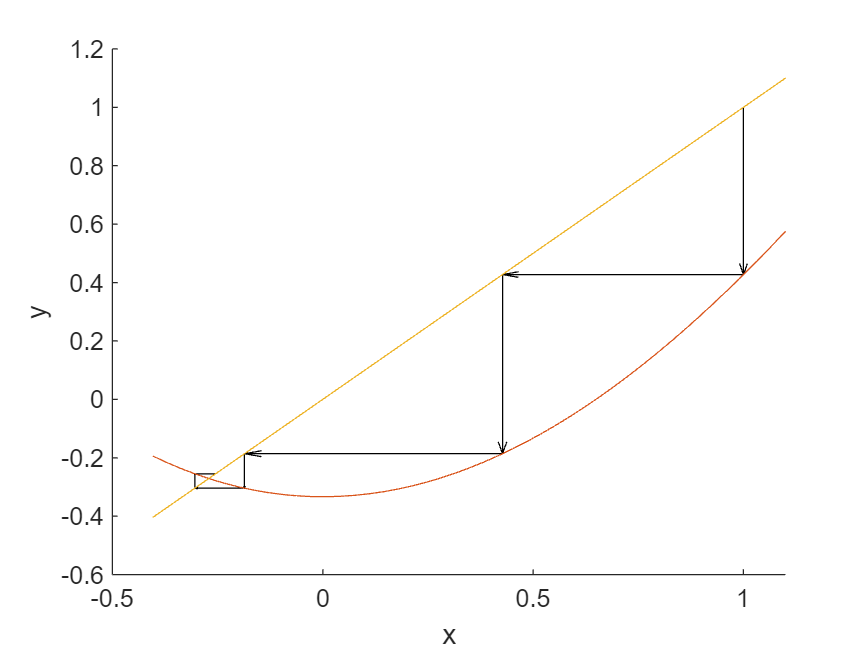

f = @(x)(x/3+x.^2-exp(x)/3); % iteration founction, remember to add '.'
x = 1; % initial values
t = 3;% iteration times, where t starts from 0
graphAnalysis(f,x,t)

Method III:

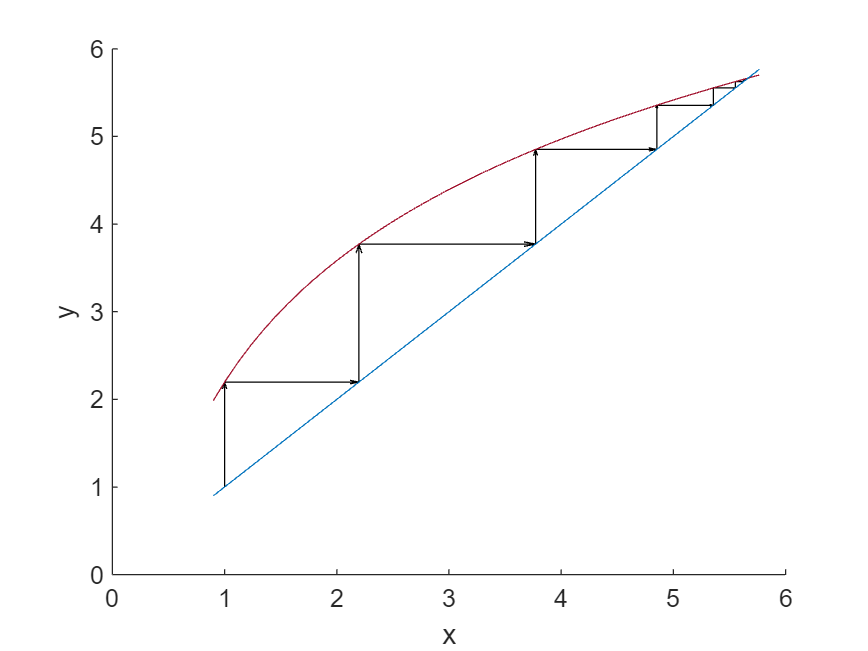

f = @(x)(2*log(3*x)); % iteration founction, remember to add '.'
x = 1; % initial values
t = 100;% iteration times, where t starts from 0
graphAnalysis(f,x,t)

graphAnalysis(f,x,t)

function graphAnalysis(f,x,t)
% f is the iteration function, remember to add '.'
% x is the initial values, x can be a vector
% t is the iteration times, where t starts from 0
clf
mini = x;% range
maxi = x;
for i = 0:t
    y = f(x);
    hold on;
    quiver(x,x,zeros(size(x)),y-x,'k',"AutoScale","off")
    quiver(x,y,y-x,zeros(size(x)),'k',"AutoScale","off")
    x = y;
    mini = min(x,mini);
    maxi = max(x,maxi);
end
hold on;
fplot(f,[min(mini)-0.1,max(maxi)+0.1]); %draw founction
hold on;
fplot(@(x)x,[min(mini)-0.1,max(maxi)+0.1]);%draw y=x
xlabel('x');
ylabel('y');
end